位相情報の重要性の確認

image1 = imread('lena256.png')

image1 = 256×256 の uint8 行列
   22   22    7   22   22    1   29    0    0   22    0    7    7    6    8    0    7    1   45   35   35   52   51   49   52   51   45   22   11   10   34   38   32   46   32   32   20   28   28   44   40   28   40   40   38   40   40   40   44   40
   22   22    7   22   22    1   29    0    0   22    0    7    7    6    0    0    1    1   45   35   35   52   51   52   52   51   45   22   11   10   34   38   32   46   32   32   20   38   28   44   40   38   40   44   38   40   44   40   44   40
   29    0    1    1    1    1    8    8    0    7    8   13    0    0    6    7    8    6    1   35   45   49   47   52   51   52   45    7   11    5   34   44   32   39   39   32   20   20   28   38   38   28   38   40   20   28   40   24   28   24
    1    7    1    7   22    7    8    6    8    8    8    6    0    6    6    8    7    8    7   22   49   49   47   52   51   52   29    8    6   12   33   44   39   77   62   46   20   19   44   40   28   20   28   4

image2 = imread('cameraman256rgb.png');
image2 = double(rgb2gray(image2))

image2 =    172   173   173   172   172   173   173   173   172   173   173   174   175   175   175   174   177   177   176   176   177   177   178   178   177   177   177   179   180   178   177   179   179   179   179   179   179   181   181   180   179   178   182   182   182   183   183   183   183   182
   174   172   172   172   173   174   173   173   173   173   172   172   174   175   174   174   177   176   175   175   177   177   177   177   176   177   177   178   179   180   180   179   179   178   177   178   179   181   181   179   178   178   182   183   183   184   183   183   184   183
   173   173   173   171   172   173   173   173   173   174   172   173   175   175   174   174   177   176   176   175   177   177   178   177   177   177   177   178   179   178   178   179   179   178   179   178   178   181   181   179   179   178   182   182   182   183   183   183   183   182
   174   171   172   172   172   174   173   173   173   174   172   172   174   174   1

f1 = fft2(image1)

f1 = 1.0e+06 *

   2.2998 + 0.0000i  -0.0202 - 0.0236i  -0.0074 - 0.1463i   0.0753 + 0.0240i  -0.0514 + 0.1011i  -0.0351 - 0.0618i  -0.0141 + 0.0172i   0.0338 - 0.0221i   0.0635 + 0.0296i   0.0131 - 0.0236i   0.0275 - 0.0727i  -0.0046 + 0.0450i  -0.0418 - 0.0152i   0.0234 - 0.0142i   0.0129 - 0.0156i   0.0097 - 0.0404i  -0.0251 - 0.0249i  -0.0506 - 0.0156i  -0.0489 + 0.0113i  -0.0451 + 0.0498i   0.0073 + 0.0553i   0.0313 + 0.0704i   0.0500 + 0.0393i   0.0656 - 0.0164i   0.0328 - 0.0399i   0.0070 - 0.0488i  -0.0229 - 0.0185i  -0.0270 - 0.0058i   0.0136 + 0.0063i   0.0096 + 0.0188i   0.0232 - 0.0148i   0.0137 - 0.0243i   0.0001 - 0.0102i  -0.0306 - 0.0256i  -0.0247 - 0.0089i  -0.0246 + 0.0040i  -0.0119 + 0.0329i   0.0098 + 0.0255i   0.0196 + 0.0054i   0.0259 + 0.0031i   0.0115 - 0.0082i   0.0006 - 0.0228i  -0.0061 - 0.0158i  -0.0078 - 0.0089i  -0.0128 - 0.0026i  -0.0078 - 0.0020i  -0.0004 + 0.0060i  -0.0083 + 0.0026i   0.0007 + 0.0079i   0.0030 + 0.0022i
  -0.0960 + 0.0611i   0.2022 + 0.

f2 = fft2(image2)

f2 = 1.0e+06 *

   8.5821 + 0.0000i   0.5546 + 1.3093i   0.4510 - 0.3618i   0.0418 - 0.2950i  -0.1513 - 0.1993i  -0.0770 - 0.0400i  -0.0382 - 0.0723i  -0.1268 + 0.1230i   0.0812 - 0.0076i   0.0542 + 0.0481i   0.0276 - 0.0904i  -0.0094 + 0.0106i  -0.0221 - 0.0445i   0.0030 - 0.0233i   0.0084 + 0.0490i  -0.0197 - 0.0431i  -0.0162 + 0.0305i   0.0098 - 0.0072i   0.0323 - 0.0184i  -0.0227 - 0.0260i  -0.0078 - 0.0227i  -0.0239 + 0.0084i   0.0090 + 0.0244i   0.0081 - 0.0219i   0.0108 + 0.0151i   0.0219 - 0.0281i  -0.0087 + 0.0077i   0.0012 - 0.0375i   0.0005 + 0.0035i  -0.0254 - 0.0106i   0.0246 + 0.0350i  -0.0090 - 0.0165i   0.0222 + 0.0044i  -0.0086 - 0.0225i   0.0195 + 0.0134i  -0.0234 - 0.0163i   0.0189 - 0.0008i  -0.0252 - 0.0148i   0.0238 + 0.0099i  -0.0181 + 0.0062i   0.0326 - 0.0045i  -0.0269 - 0.0115i   0.0266 - 0.0024i  -0.0335 + 0.0036i   0.0180 - 0.0149i  -0.0226 + 0.0108i   0.0107 - 0.0017i  -0.0049 + 0.0067i   0.0213 - 0.0153i  -0.0121 + 0.0084i
   0.7800 - 0.8262i  -0.6513 - 0.

f1abs = abs(fftshift(f1))

f1abs = 1.0e+06 *

    0.0033    0.0021    0.0045    0.0022    0.0003    0.0019    0.0013    0.0043    0.0060    0.0014    0.0018    0.0018    0.0054    0.0061    0.0034    0.0013    0.0034    0.0009    0.0019    0.0017    0.0059    0.0041    0.0045    0.0026    0.0034    0.0032    0.0046    0.0022    0.0010    0.0008    0.0040    0.0046    0.0038    0.0020    0.0020    0.0029    0.0025    0.0069    0.0019    0.0048    0.0017    0.0040    0.0028    0.0020    0.0013    0.0021    0.0032    0.0041    0.0024    0.0012
    0.0044    0.0065    0.0039    0.0035    0.0043    0.0030    0.0023    0.0045    0.0031    0.0036    0.0021    0.0024    0.0029    0.0055    0.0038    0.0027    0.0011    0.0042    0.0024    0.0038    0.0024    0.0016    0.0059    0.0049    0.0016    0.0028    0.0024    0.0026    0.0029    0.0009    0.0014    0.0013    0.0036    0.0023    0.0028    0.0010    0.0023    0.0043    0.0044    0.0019    0.0034    0.0037    0.0018    0.0032    0.0012    0.0002    0.0018    0.0038

f2abs = abs(fftshift(f2))

f2abs = 1.0e+06 *

    0.0000    0.0002    0.0000    0.0001    0.0001    0.0002    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0000    0.0001    0.0001    0.0002    0.0003    0.0001    0.0001    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0002    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0001    0.0003    0.0003    0.0002    0.0001    0.0003
    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002    0.0000    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0002    0.0000    0.0001    0.0001    0.0002    0.0002    0.0001    0.0000    0.0001    0.0000    0.0002    0.0001    0.0001    0.0001    0.0001    0.0003    0.0002    0.0001    0.0002    0.0003    0.0003    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0000    0.0002    0.0001    0.0001    0.0002    0.0001    0.0002    0.0003

f1phase = f1 ./ f1abs

f1phase = 1.0e+02 *

   6.8960 + 0.0000i  -0.0978 - 0.1139i  -0.0166 - 0.3265i   0.3349 + 0.1066i  -1.9708 + 3.8759i  -0.1805 - 0.3181i  -0.1088 + 0.1326i   0.0779 - 0.0510i   0.1065 + 0.0496i   0.0928 - 0.1676i   0.1526 - 0.4037i  -0.0251 + 0.2461i  -0.0779 - 0.0283i   0.0387 - 0.0234i   0.0377 - 0.0456i   0.0779 - 0.3232i  -0.0731 - 0.0727i  -0.5391 - 0.1663i  -0.2547 + 0.0588i  -0.2636 + 0.2907i   0.0123 + 0.0930i   0.0772 + 0.1736i   0.1117 + 0.0877i   0.2528 - 0.0634i   0.0956 - 0.1165i   0.0223 - 0.1549i  -0.0499 - 0.0403i  -0.1220 - 0.0262i   0.1320 + 0.0611i   0.1192 + 0.2324i   0.0577 - 0.0369i   0.0297 - 0.0526i   0.0003 - 0.0266i  -0.1551 - 0.1298i  -0.1264 - 0.0453i  -0.0841 + 0.0138i  -0.0472 + 0.1306i   0.0142 + 0.0372i   0.1053 + 0.0290i   0.0538 + 0.0065i   0.0677 - 0.0483i   0.0016 - 0.0576i  -0.0215 - 0.0557i  -0.0389 - 0.0443i  -0.0992 - 0.0204i  -0.0364 - 0.0095i  -0.0014 + 0.0189i  -0.0203 + 0.0062i   0.0027 + 0.0326i   0.0248 + 0.0185i
  -0.2183 + 0.1389i   0.3091

f2phase = f2 ./ f2abs

f2phase = 1.0e+05 *

   2.4520 + 0.0000i   0.0279 + 0.0660i   0.1983 - 0.1591i   0.0031 - 0.0222i  -0.0109 - 0.0144i  -0.0044 - 0.0023i  -0.0047 - 0.0089i  -0.0160 + 0.0155i   0.0193 - 0.0018i   0.0098 + 0.0087i   0.0034 - 0.0111i  -0.0011 + 0.0013i  -0.0027 - 0.0055i   0.0002 - 0.0019i   0.0005 + 0.0028i  -0.0010 - 0.0023i  -0.0009 + 0.0016i   0.0012 - 0.0009i   0.0018 - 0.0011i  -0.0020 - 0.0023i  -0.0003 - 0.0010i  -0.0030 + 0.0011i   0.0009 + 0.0025i   0.0018 - 0.0050i   0.0008 + 0.0011i   0.0016 - 0.0021i  -0.0004 + 0.0003i   0.0000 - 0.0013i   0.0001 + 0.0006i  -0.0021 - 0.0009i   0.0080 + 0.0113i  -0.0010 - 0.0018i   0.0061 + 0.0012i  -0.0024 - 0.0062i   0.0027 + 0.0018i  -0.0055 - 0.0039i   0.0011 - 0.0001i  -0.0067 - 0.0039i   0.0020 + 0.0008i  -0.0016 + 0.0005i   0.0035 - 0.0005i  -0.0027 - 0.0011i   0.0011 - 0.0001i  -0.0011 + 0.0001i   0.0017 - 0.0014i  -0.0007 + 0.0003i   0.0004 - 0.0001i  -0.0002 + 0.0003i   0.0038 - 0.0027i  -0.0004 + 0.0003i
   0.1271 - 0.1346i  -0.0876

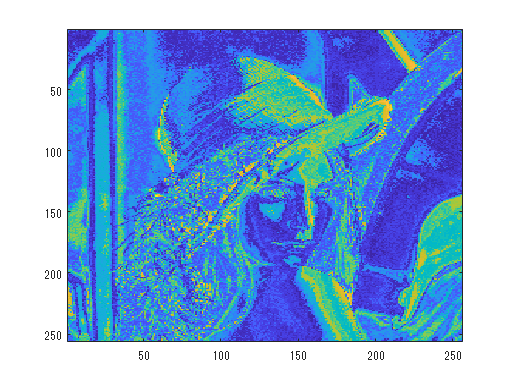

imagesc(image1)

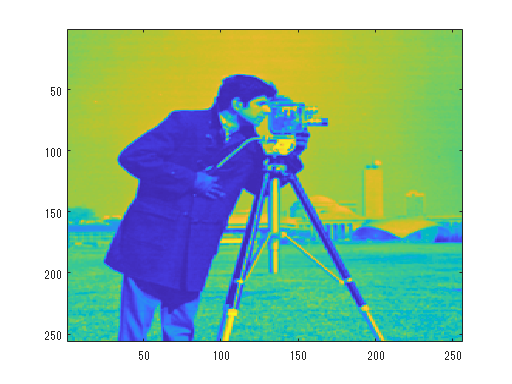

imagesc(image2)

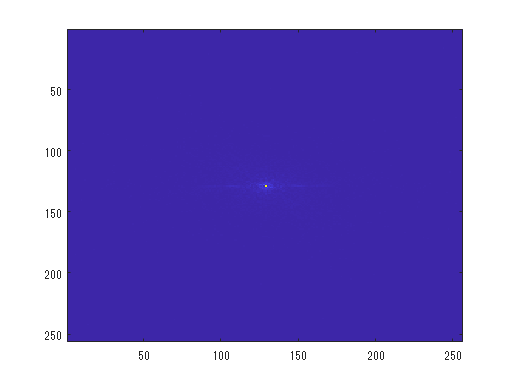

imagesc(f1abs)

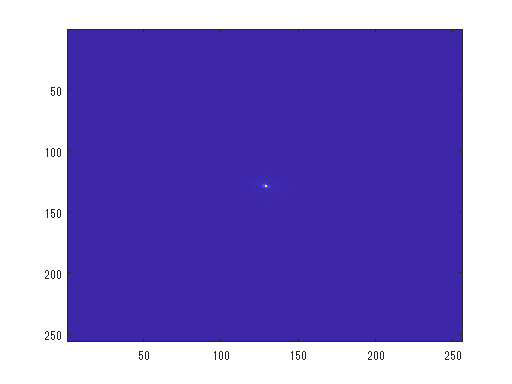

imagesc(f2abs)

rf1 = real(ifft2())

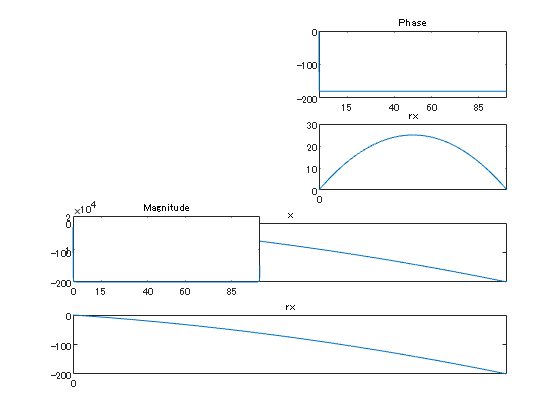

t = 0:1/100:10-1/100;                     % Time vector
x = - t.^2 + 10*t; %sin(2*pi*15*t) + sin(2*pi*40*t);      % Signal
y = fft(x);                               % Compute DFT of x
m = abs(y);                               % Magnitude
y(m<1e-6) = 0;
p = unwrap(angle(y));                     % Phase
f = (0:length(y)-1)*100/length(y);        % Frequency vector

rx = ifft(y);

subplot(2,2,1)

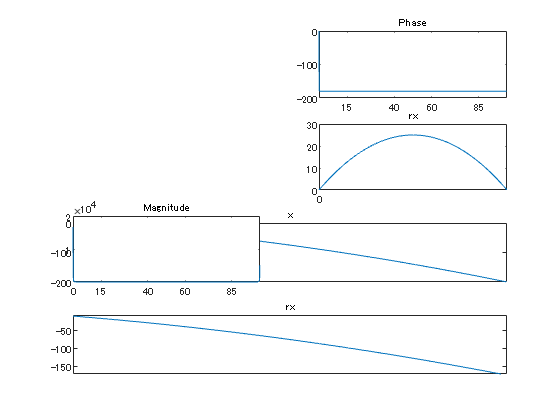

plot(f,m)
title('Magnitude')
ax = gca;
ax.XTick = [15 40 60 85];

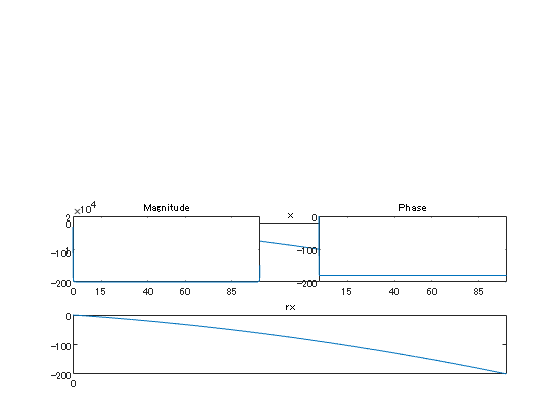


subplot(2,2,2)
plot(f,p*180/pi)
title('Phase')
ax = gca;
ax.XTick = [15 40 60 85];

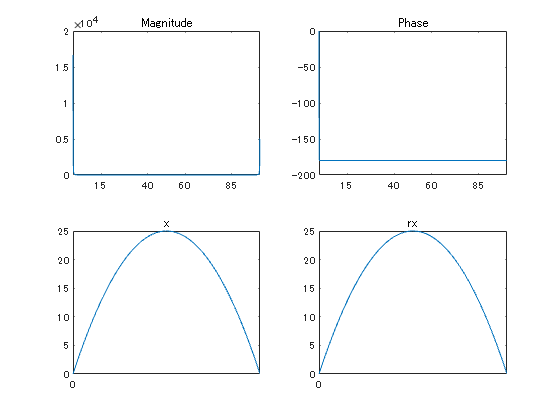



subplot(2,2,3)
plot(t,x)
title('x')
ax = gca;
ax.XTick = [0 5];

subplot(2,2,4)
plot(t,real(rx))
title('rx')
ax = gca;
ax.XTick = [0 5];

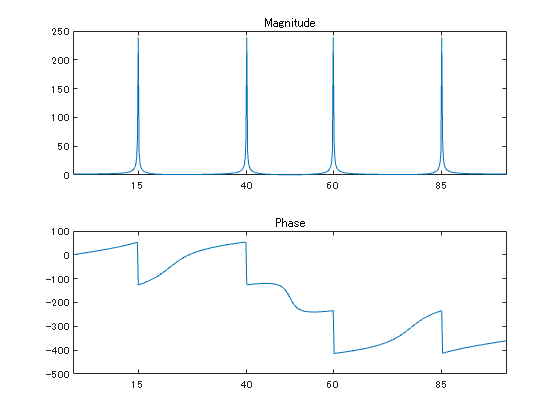

n = 512;
y = fft(x,n);
m = abs(y);
p = unwrap(angle(y));
f = (0:length(y)-1)*100/length(y);

subplot(2,1,1)
plot(f,m)
title('Magnitude')
ax = gca;
ax.XTick = [15 40 60 85];

subplot(2,1,2)
plot(f,p*180/pi)
title('Phase')
ax = gca;
ax.XTick = [15 40 60 85];

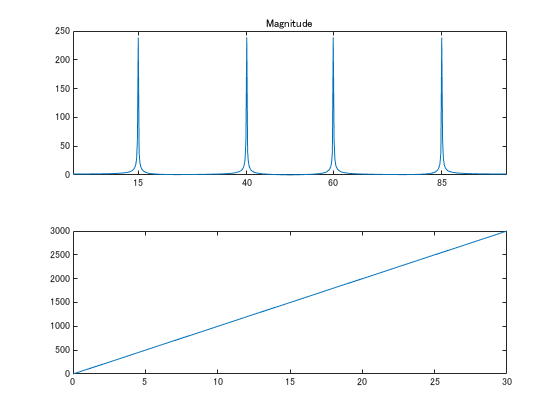

x = 0:30;
for i = 0:100
    y = i * x;
    plot(x, y)
    ylim([0 3000])
    pause(0.1);
end

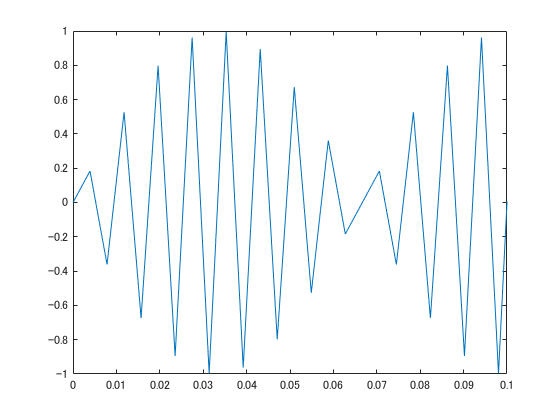

t = 0:1/255:1;
x = sin(2*pi*120*t);
y = ifft(fft(x));

figure
plot(t,x)

xlim([0, 0.1])